Let's solve the following optimization problem $\min H(x)=\frac{1}{2}(x_1^2 + 3x_2^2 - 2x_1x_2) = \frac{1}{2}x^TWx$, such that $2x_1-x_2=1$

We have to first extract the W, which on element W[i,i] will have the weight of $x_i^2$

W = [1 -2; 0 3];
W = (W+W')/2 %symmetrization

W =      1    -1
    -1     3


Now to the solution. First the data of the constraint

J = [2 -1]; y = 1;
J_dash_w = W \ J' / (J * (W \ J'));
x_star_w = J_dash_w * y

x_star_w =     0.5556
    0.1111


Solution with an identity weighting matrix (closest to the origin)

x_star = pinv(J) * y

x_star =     0.4000
   -0.2000


Contour plot

x1 = linspace(-1,1); x2 = linspace(-1,1);
[X1,X2] = meshgrid(x1,x2);
H = 1/2*(X1.^2 + 3*X2.^2 - 2*X1.*X2);
contour(X1,X2,H,53); %we don't have circles because we used a different weighting matrix W than eye

grid; hold on;

Constraint and solution plot

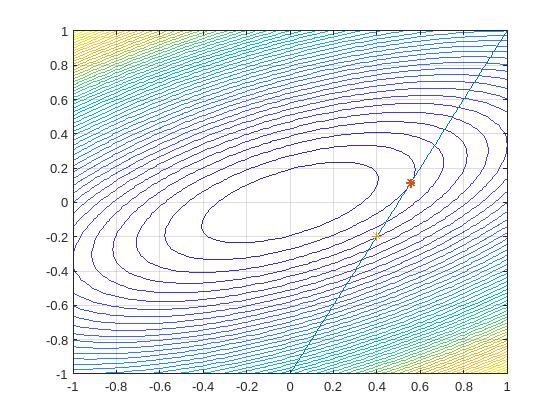

x = sym("x",[2,1]);
eq = J*x == y;
fimplicit(eq,[-1,1]); 
plot(x_star_w(1),x_star_w(2),"*","linewidth",2);
plot(x_star(1),x_star(2),"*");